# Ejercicio 2

## Planta



% s = tf('s');
% G = 10/( (s+4)*(s+2)*(s+0.1) );
G1 = zpk([], [-4 -2 -.1], 10)


G1 =
 
          10
  -------------------
  (s+4) (s+2) (s+0.1)
 
Continuous-time zero/pole/gain model.
Model Properties



% PID con ZN
K = 12.5;
T = 22;
L = 1.0;

Kp = .9*T / (L*K);
tau_i = 3.33*L;
Ki = Kp / tau_i;


## Retardo

G2 = tf(1,[1], 'inputDelay', 1)


G2 =
 
  exp(-1*s) * (1)
 
Continuous-time transfer function.
Model Properties


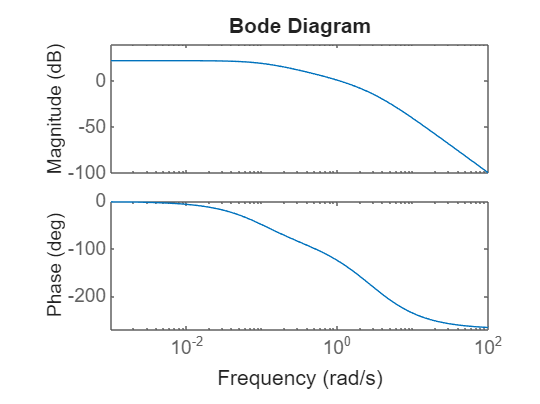

% G22 = Ntf(1,[1], 'inputDelay', Dm)
bode(G1);

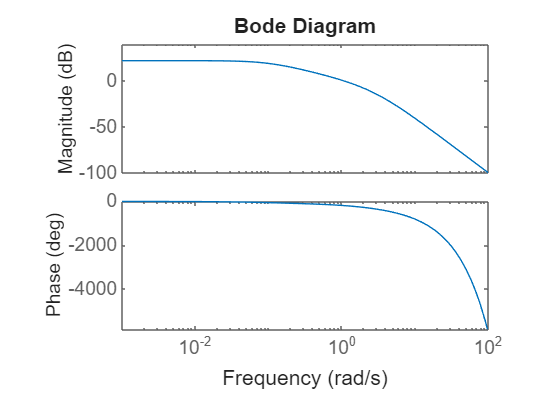

bode(G1*G2);